clear; close all;


[ProgressClassFile, ProgressClassFolder, tf] = uigetfile("F:\YuLab\Work\GPS\Data\*.mat");
if ~tf
    return;
end
ProgressClassPath = fullfile(ProgressClassFolder, ProgressClassFile);

load(ProgressClassPath);

FigFolder = fullfile(ProgressClassFolder, "TestFigs");
if ~isfolder(FigFolder)
    mkdir(FigFolder);
end

FP = obj.MixedFP;
cued_this = find(obj.CueUncue==0);


data = obj.BehavTable(ismember(obj.BehavTable.Label, ["Control", "Chemo"]),:);

session_control = unique(data.SessionDate(data.Label=="Control"));
session_chemo = unique(data.SessionDate(data.Label=="Chemo"));
n_session = length(session_chemo);
if length(session_control) ~= n_session
    error("number of control and chemo session dont match.")
end


session_compare = zeros(height(data), 1);
for s = 1:n_session
    session_compare(ismember(data.SessionDate, [session_control(s) session_chemo(s)])) = s;
end

data = addvars(data, session_compare, 'NewVariableNames', 'Compare');


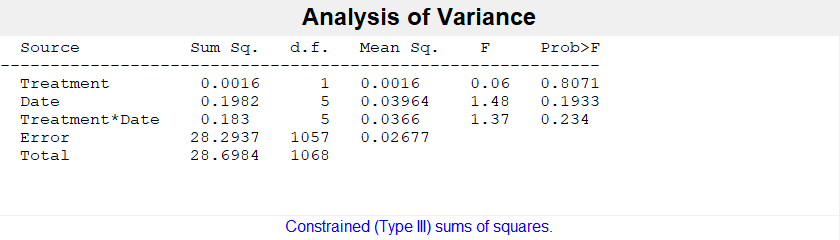

id_l = data.PortCorrect==1 & data.Cued==0;
id_r = data.PortCorrect==2 & data.Cued==0;

[p_l,tbl_l,stats_l,terms_l] = anovan(data.HoldDuration(id_l), {data.Label(id_l), data.Compare(id_l)}, ...
    'varnames', {'Treatment', 'Date'}, 'model', 'full');

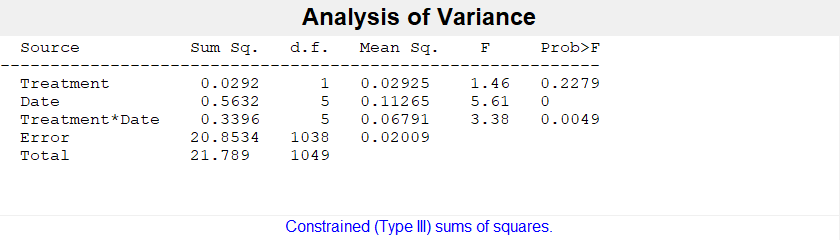


[p_r,tbl_r,stats_r,terms_r] = anovan(data.HoldDuration(id_r), {data.Label(id_r), data.Compare(id_r)}, ...
    'varnames', {'Treatment', 'Date'}, 'model', 'full');

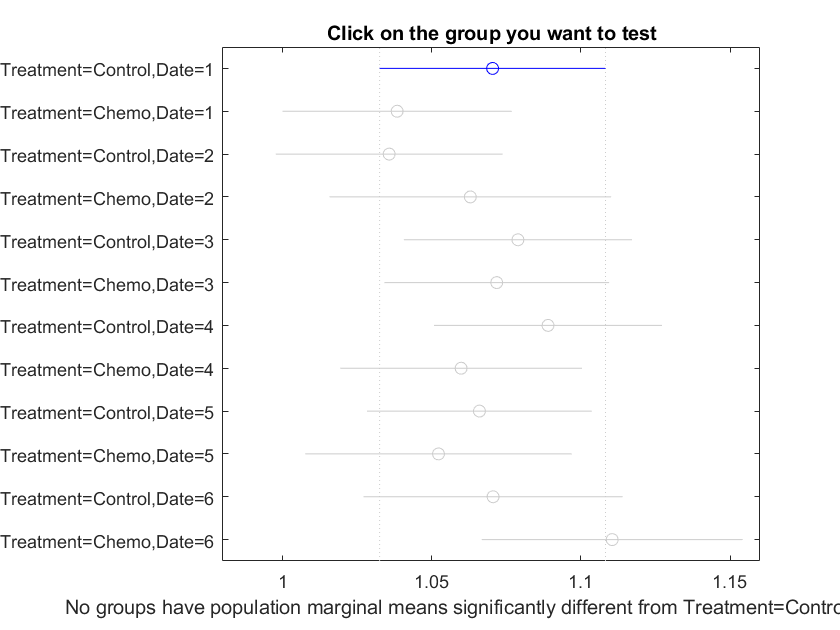


figure(); multcompare(stats_l, "Dimension", [1 2]);

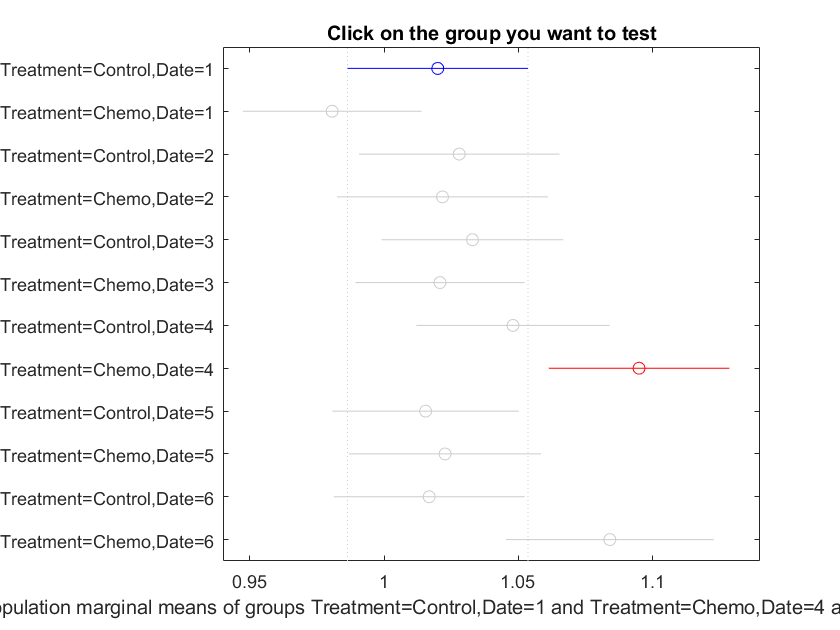


figure(); multcompare(stats_r, "Dimension", [1 2]);

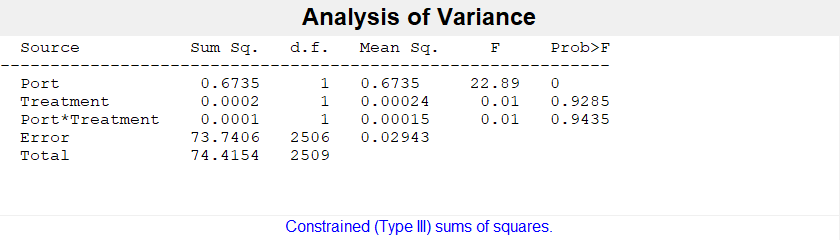

[p,tbl,stats,terms] = anovan(data.HoldDuration, {data.PortCorrect, data.Label}, ...
    'varnames', {'Port', 'Treatment'}, 'model', 'full');

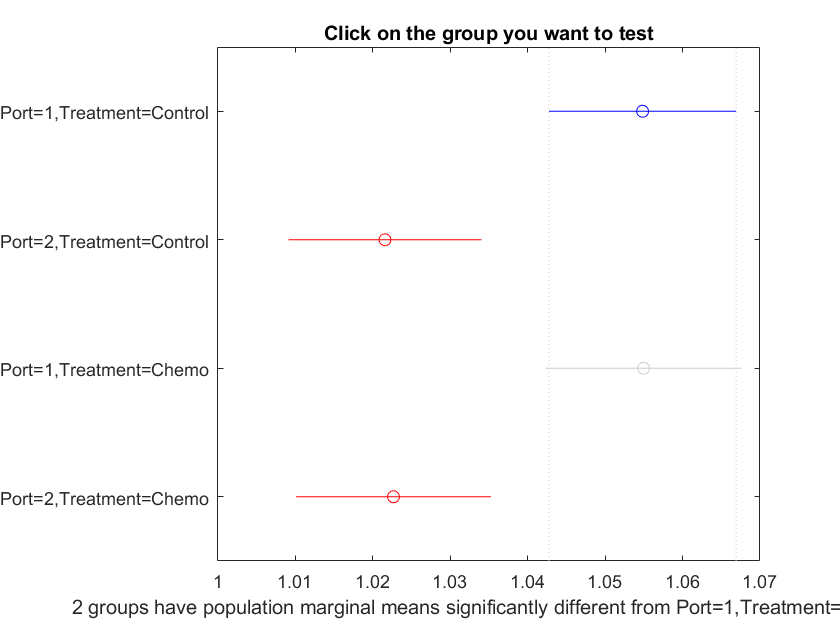

figure(); multcompare(stats, "Dimension", [1 2]);